# Propagation of Uncertainty Midterm

Warm up problems

1) The gravity constant $g$ is to be determined by measuring the resonant frequency of a simple pendulum $2\pi\nu = \sqrt{g/l$. If we require $\sigma_g/g = 0.1\%$, what is the relative precision required for the measurements of $l$ and $\nu$?

Solve for $g=(2\pi)^2\nu^2l$, which is a product of 2 (or 3) empirical factors: $\nu, \nu, l$. Using formula from [https://en.wikipedia.org/wiki/Propagation_of_uncertainty#Example_formulae](https://en.wikipedia.org/wiki/Propagation_of_uncertainty#Example_formulae) with the assumption that the variables are all independent, i.e., $\sigma_{AB} = 0$, the relevant form is $f=AB$, or generalize to $f=ABC$ where two of those terms are the same (and then we don't need to mess with $f=aA^b$, but I'll derive it anyway now). Let $y = x^2$, then $\sigma_y = 2x\sigma_x \rightarrow \sigma_y/y = 2x \sigma_x/x^2 = 2\sigma_x/x. $ If there are other factors, they all have to add in quadrature -- no cancellation allowed, and like vector components, each error is independent (i.e., orthogonal). So $\frac{\sigma_g}{g} = \sqrt{2\left(\frac{\sigma_\nu}{\nu}\right)^2+\left(\frac{\sigma_l}{l}\right)^2} = 0.1\%$, where the 2 comes from $\nu^2$. Each term in the radical is positive definite, so that puts a hard minimum that $\sigma_l < 10^{-3} l$ if the first term is $<< 0.1\%$, and $\sigma_\nu<5*10^{-4}\nu$ if the second term is negligible. Assuming its just as difficult to achieve relative precision in each term, then setting the two terms equal to $1/2*(0.1\%)^2$ = (1e-6)/2 splits the cost. Let's simulate this with some parameters and random numbers:

l = 1 + 1*sqrt(1e-6/2)*randn([1e6 1]);
nu = 1/2/pi * sqrt(9.8/1); % frequency corresponding to l=10
nu = nu + nu*sqrt(1e-6/2)/2*randn([1e6 1]);
g = (2 * pi * nu) .^2 .* l;
fprintf('l=%.5f±%.5f, COV=%.4f%%\n', mean(l), std(l), std(l)/mean(l)*100)

l=1.00000±0.00071, COV=0.0707%


fprintf('nu=%.5f±%.5f, COV=%.4f%%\n', mean(nu), std(nu), std(nu)/mean(nu)*100)

nu=0.49823±0.00018, COV=0.0354%


fprintf('g=%.4f±%.4f, COV=%.4f%%\n', mean(g), std(g), std(g)/mean(g)*100)

g=9.8000±0.0098, COV=0.1000%


Run it a few times with different random numbers, I think you'll convince yourself the analytic AND empirical methods work. What's the probability we don't know what we're doing with this recipe, and we get the same answers taking these two very independent paths? And BTW, to verify the analytic model, we *simulated* 3 million (times maybe 20 repetitions that I did before getting all the coefficients and parameters right) = 60 million virtual measurements -- without breaking a sweat. That's pretty powerful.  

## Caltech Physics 3 test

- The thickness $d$ of the base of a cylindrical can is computed by measuring the outside height $H = (97.3 \pm 0.2)mm$ and the inside height $h = (97 \pm 1)mm$. What is $d$ and its uncertainty $\sigma_d$? Would a more precise measurement of $H$improve $\sigma_d$?

- A program spat out `a=12.37825m/s` with error `0.0278614` and `b=3.22395e-3m` with error `2.757823e-5`. Report these values clearly as $a\pm\sigma_a$ and $b\pm\sigma_b$, with appropriate significant figures.

- A distance $x$ is measured using a ruler of $l=300mm$, which is too short for a direct measurement. Using the ruler stepwise, it is found that the distance $x = 9l$. If the uncertainty of each measuremnet is $\sigma = 1mm$, what is the total length $x \pm \sigma_x$?

- We have 2 measurements of the same quantity obtained by two different methods: $v_1=(1.23\pm0.02)V$ and $v_2 = (1.26\pm0.01)V$. Do these two measurements agree? What's the best estimate for $v\pm\sigma_v$?

- Six voltage measurements are made across a resistor: V = [1.44 1.48 1.47 1.43 1.50 1.47]; If the resistance is measured to be $R=(15.1\pm0.1)\Omega$, what is the power dissapated by the resistor and its uncertainty $\sigma_P$?

1.  Analytically, $H = h+d \rightarrow d = H-h$. Uncertainties are independent so they add in quadrature: $\sigma_d = \sqrt{\sigma_H^2+\sigma_h^2} = \sqrt{.2^2+1^2} = 1.02$, so $d = 0.3\pm 1.02$. 

Simulation

H = 97.3 + randn([1e6,1])*.2;
fprintf('H = %.1f ± %.2f\n', mean(H), std(H)); % verify

H = 97.3 ± 0.20


h = 97+randn([1e6,1]);
fprintf('h = %.1f ± %.2f\n', mean(h), std(h));

h = 97.0 ± 1.00


d = H-h;
fprintf('d = %.2f ± %.2f\n', mean(d), std(d));

d = 0.30 ± 1.02


2. $a = 12.38\pm .03 m/s$, $b = (3.224\pm0.028)x10^{-3}
m$

3. $l = 300\pm1 mm$, $x = 9l$, 


$$\sigma_x = \sqrt{9}*\sigma_l = 3mm$
$$


Simulation

l = 300+randn(9,1e6);
x = sum(l); 
fprintf('x = %.2f ± %.2f\n', mean(x), std(x)); % 0.1f would be more justifiable

x = 2700.00 ± 3.00


4. Eyeballing, $v_1=1.25V$ and $v_2=1.25V$ are both within one standard deviation -- so they agree. But we can also model it, e.g., asking what's the joint probability that $v_1 \ge 1.25V$ and $v_2 \le 1.25V$:

v1 = 1.23+.02*randn([1e6 1]);
v2 = 1.26+.01*randn([1e6 1]);
bool = v1 >= 1.25 & v2 <= 1.25;
fprintf('v1 = %.3f ± %.3f\n', mean(v1), std(v1));

v1 = 1.230 ± 0.020


fprintf('v2 = %.3f ± %.3f\n', mean(v2), std(v2));

v2 = 1.260 ± 0.010


fprintf('joint prob = %.3f\n', sum(bool)/1e6)

joint prob = 0.025


Not a big probability. But is that the right probability -- it's the likelihood that *for a single pair of measurements*,  *both* overlap. Rather we want the *independent *probabilities:

fprintf('P{v1>=1.25} = %.3f, P{v2<=1.25} = %.3f\n', ...
    sum([v1>=1.25 v2<=1.25])/1e6)

P{v1>=1.25} = 0.159, P{v2<=1.25} = 0.159


So each has a 16% chance. We can visualize this graphically: 

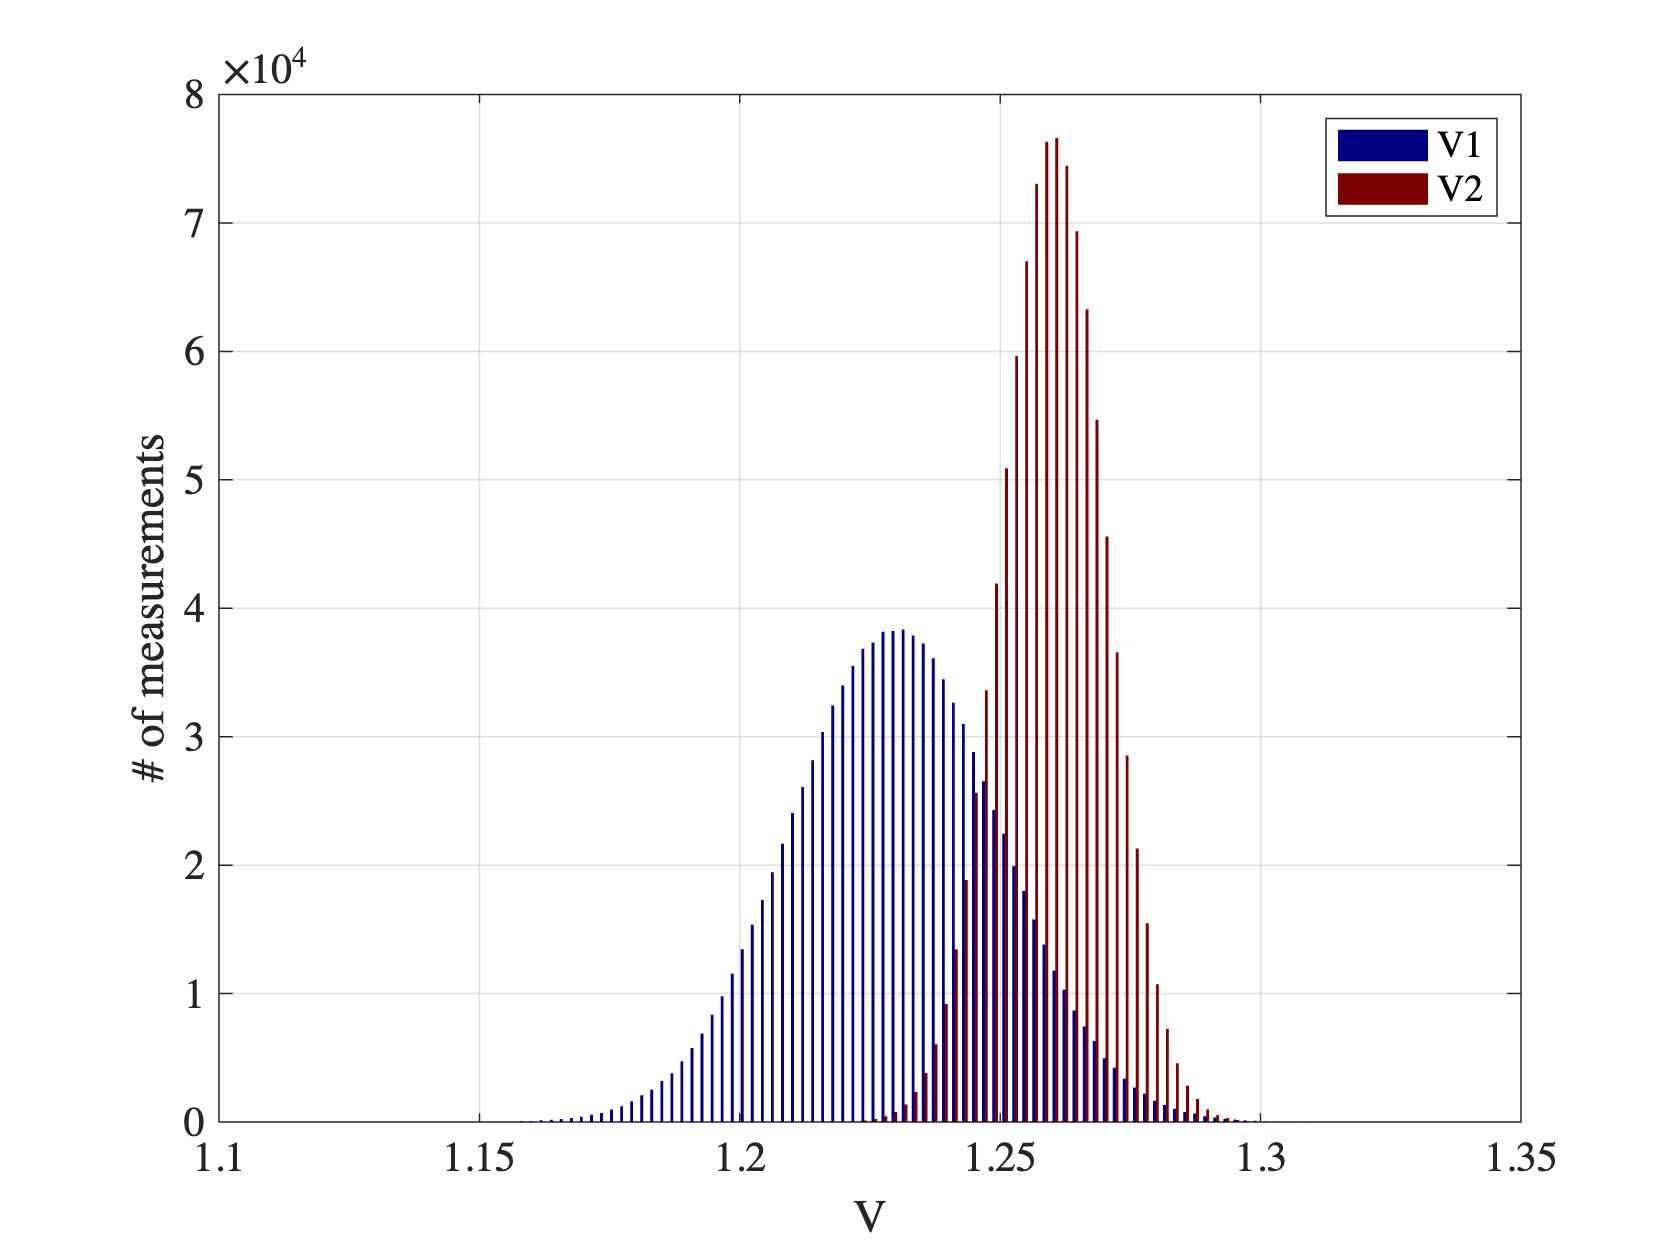

hist([v1 v2], 100); 
xlabel('V'); ylabel('# of measurements')
legend('V1','V2'); grid;

Looking at the data this way, the two mean results seem compabible. 

So if we accept both these results, what's the most likely value and uncertainty of this parameter? If we just take the mean and std of all the data together 

fprintf('best v = %.3f±%.3f\n', mean([v1;v2]), std([v1; v2]))

best v = 1.245±0.022


we gate a value half way between each mean, and a larger std than either. The problem with this is we're averaging what is clearly not a single Gaussian distribution as if it were. We're ignoring the individual $\sigma_{v1}$ and $\sigma_{v2}$. Doesn't the lower uncertainty in $v_2$ suggest that result is "better" and should be weighted more than the $v_1$? Qualitatively, doesn't the $v_1$ result suggest the true answer is likely a little left of 1.26, and with a smaller uncertainty because the right-side tail is less probable? How's this for a weighed average: 

vbest = (.01*1.23+.02*1.26)/(.01+.02)

vbest = 1.2500

And doesn't that seem exactly the most probable answer -- where both curves are their respective sigma's from the peak. I'll leave it as an exercise to find the corresponding $\sigma_{vbest}$. 

6. $P = V^2/R$ and $\sigma_P^2 = P^2*(2(\sigma_V/V)^2+(\sigma_R/R)^2)$. I multiplied all P's and $\sigma_P$'s by the conversion factor (1000mW/1W) for more natural units. 

V = [1.44 1.48 1.47 1.43 1.50 1.47]; % volts
R = 15.1; % ohms
P = mean(V)^2/R;
sigmaP = P*sqrt(2*(std(V)/mean(V))^2+(.1/R)^2);
fprintf('P = (%.2f±%.2f)mW\n',P*1000,sigmaP*1000);

P = (142.13±3.67)mW


Again we can simulate the propagation of uncertainty: 

Vsim = mean(V) + std(V) * randn([1e6 1]);
Rsim = 15.1 + .1 * randn([1e6 1]);
Psim = Vsim .^2 ./ Rsim;
fprintf('Psim = %.2f±%.2fmW\n', mean(Psim)*1000, std(Psim)*1000)

Psim = 142.18±5.11mW


Interesting that Psim is a tiny bit larger than P, and the uncertainty is much larger. Why? I suspect because V isn't Gaussian, and certainly V^2 isn't -- squaring makes the outliers even bigger and smaller. What if we introduce a new variable called Vsq:

Vsq = V .^2;
Psq = mean(Vsq)/R;
sigmaPsq = Psq * sqrt((std(Vsq)/mean(Vsq))^2 + (.1/R)^2); % no factor of 2 on 1st term
fprintf('Pvsq = %.2f±%.2fmW\n', Psq*1000, sigmaPsq*1000)

Pvsq = 142.17±5.10mW


That agrees much better with the big simulation. So why? Because the distribution of V, i.e., mean and std, are different than the distribution of V^2

fprintf('V = %.2f±%.2f\n', mean(V), std(V));

V = 1.46±0.03


fprintf('sqrt(Vsq) = %.2f±%.2f\n',sqrt(mean(Vsq)),sqrt(std(Vsq)));

sqrt(Vsq) = 1.47±0.28


Of course,  sqrt(std(V.^2)) $\ne$ std(V) ... if $y = (x\pm\sigma_x)^2$, then $(\sigma_y / y)^2 = 2(\sigma_x/x)^2 \rightarrow \sigma_y = \sqrt{2}x \sigma_x$

sigV2 = sqrt(2)*mean(Vsq)*std(V)

sigV2 = 0.0786

sigPsq = Psq * sqrt((sigV2/mean(Vsq))^2 + (.1/R)^2);
fprintf('Pvsq = %.2f±%.2fmW\n', Psq*1000, sigPsq*1000)

Pvsq = 142.17±5.29mW


Finally agreement in the propgatated uncertainty (to 2 sig figs). 